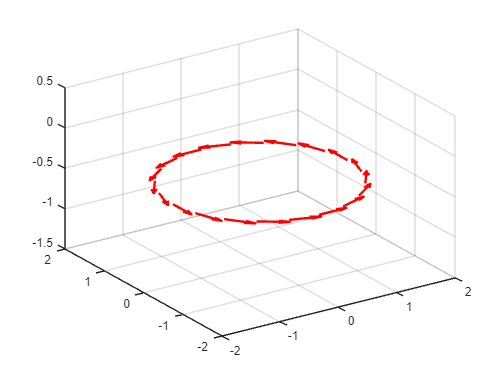

clearvars ;          %Clear all variables from the workspace
clc;          %Clear command window
clf;          %Clear all elements on figures

nl=1;     %the number of wire loops in your simulation.One for a configuration called 
           % a ______________? %Two or more for a configuration referred to as a __________________? 

ds=0.1;             %ds differential longitud , 0.1


x= -5:ds:5; y=-5:ds:5;  z=-5:ds:5; %Define x, y and z vectors, all equal, ranging from -5 to 5, in steps of ds.
                                    %This will define our 3D working space.
                                    
                                    %When correctly done, each vector will
                                    %be appear in the Workspace as a 1x101
                                    %double array.


Lx= length(x); 
Ly= length(y); 
Lz= length(z);   %Using the length(A) function, where A can be a vector or array, 
                  %declare Lx, Ly and Lz variables, setting them
 %equal to the number of elements in the x, y and z vectors.  
rw= 0.2;   %wire thickness, and minimum distance use a value of 0.2.

I=300;     %electrical current in Amps, declare the associate electric current
           %(use value of 300 Amperes).

mo=4*pi*1e-7;   %Space permeability
km=mo*I/(4*pi);  %magnetic constant   


N=20;   %points per loop, that will define the # of points per loop.
R=1.5;  %Loops radii, as the radious if the wire, use 1.5 as default.                   
sz=1;  %loop step in the z axis direction, setting it equal to 1. This will represent the loop step size in the z axis direction.


s=1;  %Declare an s variable (equal to 1), representing the loop "number".

dtheta=2*pi/N;   %Define the "differential angle step" (dtheta) with respect to the center 
            %of the circular wire (coil), consider that it has to cover an
        %angular displacement of 2*pi. angle step

dl=R*dtheta; %Define the "dl" length differential, coupled with the associated dtheta.   
      %Consider that dtheta is in radians.loop length differential

                            
ang=0:dtheta:2*pi-dtheta;    %Define a vector called "ang" (for angle), 
         %ranging from 0 to 2*pi-dtheta, in steps of dtheta.
        %This will store angle values to complete a cycle with steps dtheta, around the coil.
for i=1:nl %for every loop of the solenoid

    Px(s:s+N-1)=R*cos(ang);           %X position of every current element
    Py(s:s+N-1)=R*sin(ang);            %Y position of every current element
    Pz(s:s+N-1)=-nl/2*sz+(i-1)*sz;     %Z position of every current element

    dx(s:s+N-1)=-Py(s:s+N-1)*dtheta;  %X increment of every current differential
    dy(s:s+N-1)=Px(s:s+N-1)*dtheta;   %Y increment of every current differential

    s=s+N;                         %Next loop

end

dz(1:N*nl)=0;                          %Comment        

figure(1)
quiver3(Px,Py,Pz,dx,dy,dz,0.5,'-r','LineWidth',2)

%Uncomment for setting a proper viewing perspective.
view(-34,33) 

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Magnetic-field Calculation & Visualization %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


%Using the results obtained from the Biot-Savart law, get the B-field 
%at each point in space, around the current loop.


dBx(1:Lx,1:Ly,1:Lz)=0; dBy=dBx; dBz=dBx;   %Create three, 3x3 equal arrays, dBx,dBy & dBz, each spanning from 1
                   %to Lx, 1 to Ly and 1 to Lz, and 
                    %initialize all values to zero. You should 
                   %obtain in the workspace, three 101x101x101 objects (dBx, dBy, dBz) 
                                           


tic
for I=1:Lx                       %Open a for loop using "I" as index, going from 1 to Lx.  
   for J=1:Ly                  %Same but for Ly, use a "J" index.
       for K=1:Lz              %Same but for Lz, use a "K" index.   

           for L=1:nl*N           

            %<inside the 4th loop>


           rx= x(I)-Px(L);     %Write here the rx component
           ry= y(J)-Py(L);     %Same but for the ry component
           rz=z(K)-Pz(L);     %Same but for the ry component

           r=sqrt(rx^2+ry^2+rz^2);    %Get the magnitude

           r3=r^3;                         %Declate an r3 variable
                                            %equal to the third power of r
   
            % Using Biot-Savart´s original expression, use a generic
            % dl = (dx)i+(dy)j and r = (rx)i+(ry)j+(rz)k to compute the 
            % cross product between dl and r, to find three independent 
            % expression for the components of the B-fiel we want to
            % compute, dBx(I,J,K), dBy(I,J,K) and dBz(I,J,K). Do not forget
            % to update or rewrite the former components, between each
            % cycle.

          %dl = (dx)*I+(dy)*J;             
         dBx(I,J,K)=dBx(I,J,K)+km*dy(L)*rz/r3;              
         dBy(I,J,K)=dBy(I,J,K)+km*dx(L)*rz/r3;                
         dBz(I,J,K)=dBz(I,J,K)+km*(dx(L)*ry-dy(L)*rx)/r3;

            %<inside the 4th loop>

           end   %Close the 4th loop

       end    %Close the 3rd loop   
   end   %Close the 2nd loop
end    %Close the 1st loop
toc

Elapsed time is 5.002741 seconds.


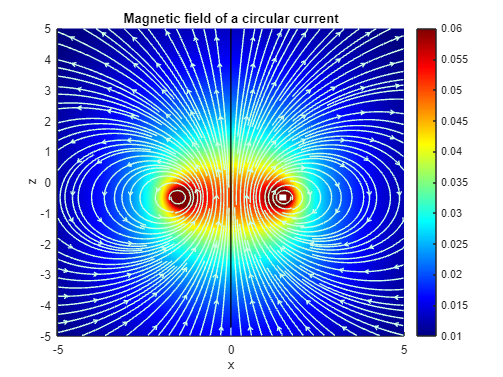

ans = 5

ans = 4.9881

ans = 4.9643

ans = 4.9285

ans = 4.8809

ans = 4.8213

ans = 4.7500

ans = 4.6667

ans = 4.5717

ans = 4.4648

ans = 4.3462

ans = 4.2159

ans = 4.0740

ans = 3.9205

ans = 3.7556

ans = 3.5793

ans = 3.3918

ans = 3.1934

ans = 2.9843

ans = 2.7649

ans = 2.5356

ans = 2.2970

ans = 2.0502

ans = 1.7963

ans = 1.5370

ans = 1.2744

ans = 1.0112

ans = 0.7496

ans = 0.4909

ans = 0.2334

ans = -0.0287

ans = -0.3040

ans = -0.6013

ans = -0.9254

ans = -1.2764

ans = -1.6511

ans = -2.0462

ans = -2.4587

ans = -2.8867

ans = -3.3292

ans = -3.7853

ans = -4.2546

ans = -4.7367

Bmag=sqrt(dBx.^2+dBy.^2+dBz.^2);    

centery=round(Ly/2);                
Bx_xz=squeeze(dBx(:,centery,:));    
Bz_xz=squeeze(dBz(:,centery,:));    
Bxz=squeeze(Bmag(:,centery,:));     

figure(2)                           
hold on

pcolor(x,z,(Bxz').^(1/3)); shading interp; colormap jet; colorbar 
clim([0.01 0.06])%?
h1=streamslice(x,z,Bx_xz',Bz_xz',3);                                 
set(h1,'Color', [0.8 1 0.9]);                                        
xlabel 'x'                                                           
ylabel 'z'                                                           
title 'Magnetic field of a circular current'                         
axis([-5 5,-5 5])
zz(length(ang))=0;
cp=find(x<=0); cx=cp(1);
cp=find(y<=0); cy=cp(1);                        %Centers' position
cp=find(z<=0); cz=cp(1);

cp=find(z>=-nl*sz*0.5);  cz=cp(1);       %Axial begining of solenoid

%dipole falling part
%Reseach and explain (in your own words), what is magnetic moment in general, 
%and for a permanent magnet (simple equations are allowed and expected):

mag=2000;               %Declare a variable calles "mag" (Magnetic moment of the magnet),
                        

m=0.004;                %Declare the Magnet´s mass in kg, use 0.004 to begin.
                        

w=m*-9.81;              %Calculate Magnet´s weigth in N, and store it in a var. called "w". Don´t 
                        %forget the sign.


zo=5;                   %Declarte Magnet's initial position using a var. called "zo".

dt=0.05;                %Declare a time step "dt" equal to 0.05.

zm(1)=zo;               %Declate a vector called "zm" (magnet position), and store in its first 
                        %value the Magnet's initial position var.

zmfree(1)=zo;           %Same as before, but using now a new vector called "zmfree", which stands
                        %for magnet´s position for the free fall case.


tt(1)=0;                %Declate a vector called "tt" (time), and initialize it to zero.

vz(1)=0;                %Declate a vector called "vz" (Z component for velocity), and initialize it to zero.

vzfree(1)=0;            %Same as above but using now a vector labeled as "vzfree".

cc=1;
path=animatedline;  %Use the animatedline function (use Matlab´s upper-right search function bar) to create an 
                    %animated line that has no data and adds it to the current axes. Later (a few lines below), add points to the line 
                    %in a loop using the addpoints function, add data.


while zm(cc)>-5     %Start a while loop running until the position of the magnet (dinamically), in z, 
                    %is bigger than -5 (i.e. the bottom of the canvas). 

    zm(cc)         %For diagnostics purposes, print the position of the magnet in z. 

    addpoints(path,0,zm(cc)); %Using the addpoints function mentioned above, add points (the zm(cc) ones) 
                              %to the path, centered in x=0.

    drawnow                   %Use drawnow to update and/or modify graphics objects and 
                              %want to see the updates on your canvas immediately.
    
    head=scatter(0,zm(cc), 100,'filled'); %Uncomment this line and explain what its doing. 
  
    Fm(cc)=(6*mo*I*R^2*mag*(zm(cc)))/(4*((zm(cc))^2+R^2)^(5/2));    %Magnetic force Fm(cc)

    F(cc)=Fm(cc)+w;                                                 %Net (total) force over the
                                                                    %magnet F(cc), considering Fm(cc)
                                                                    %and its weight.  
    a=F(cc)/m;      %Using the total force get the instantaneous acceleration and labet it as "a".
    pause(0.05)     %Use the pause function, with a value of 0.01, to grasp the heads magnet.


    zm(cc+1)=zm(cc)+vz(cc)*dt+0.5*a*dt*dt;    %Get new magnets position z(cc+1) using high school physics
                                            

    zmfree(cc+1)=zmfree(cc)+vzfree(cc)*dt-0.5*9.81*dt*dt;    %Do the same but for the free fall case
                                                          

    vz(cc+1)=(zm(cc+1)-zm(cc))/dt;       %Get new magnets velocity using basic velocity definition
                                         %vz(cc+1) = delta(z)/delta(t).

    
   
    vzfree(cc+1)=(zmfree(cc+1)-zmfree(cc))/dt;  %Do the same but for the free fall case,
                                                %i.e., with no magnetic braking.
   

    cc=cc+1;                    %Increase the cc counter in one unit.
    delete(head)                %Uncomment this line and explain what its doing.



end   %Close the while loop

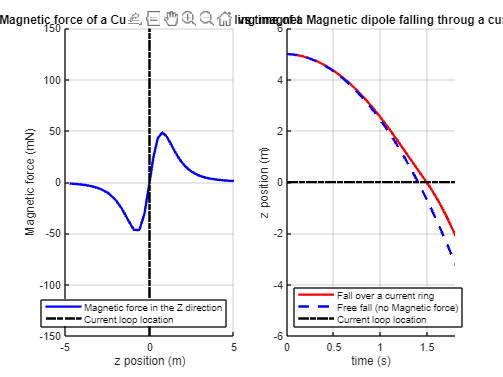

%---------------------------------------------------------------------
%--Final Part---------------------------------------------------------
%---------------------------------------------------------------------

%Ouside of the while loop, uncomment all of the following, and explain in 
%detail what it does or will do. DO NOT FORGET TO COMMENT EACHN LINE please!

figure(4)
subplot(1,2,1)

hold on
plot(zm(1:length(Fm)),1000*Fm, '-b', 'LineWidth', 2) 
plot([0,0],[-150,150],'-.k','LineWidth', 2)
grid on
xlabel 'z position (m)'
ylabel 'Magnetic force (mN)'
title 'Magnetic force of a Current ring over a falling magnet'
legend('Magnetic force in the Z direction','Current loop location','Location','southeast')

subplot(1,2,2)

hold on
tt=0:dt:(cc-1)*dt;
plot(tt,zm,'-r', 'LineWidth', 2)
plot(tt,zmfree,'--b', 'LineWidth', 2)   
plot([0,1.8],[0,0],'-.k','LineWidth', 2)
grid on
xlabel 'time (s)'
ylabel 'z position (m)'
title 'Position vs time of a Magnetic dipole falling throug a current ring'
legend('Fall over a current ring','Free fall (no Magnetic force)', 'Current loop location','Location','southwest')
axis([0 1.8 -6 6])

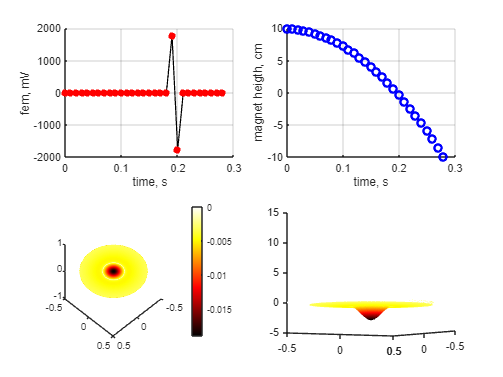

Rring=0.5;        %Define a "Rring" variable to define the ring 
                  %radius in m. Set it equal to 0.5.


zo=0.1;           %Define initial position of magnet (zo). Set it equal to 0.1.
zring=0;          %Define ring position (use "zring" variable). Set it equal to 0.
dt=0.01;          %Define time step ("dt"). Set it to 0.01.
t(1)=0;           %Define a time vector, and initialize to zero its first
                  %entry.

zm(1)=zo;       %Define a Z-position vector (zm), and initialize to "zo" its first
                %entry.
cc=1;           %Define a "cc" counter; set it equal to 1.
vz(1)=0;        %Define a vz vector; initialize its first entry to zero.

figure(3)       %Call for figure(3).

while zm(cc)>(-zo)        
%while zm(cc)>(0.0162)
pause(0.001)     
clf              
    

    [x,y,phiB1,Bz]=B_due_M(zm(cc),mag,Rring); 
    zm(cc+1)=zm(cc)+vz(cc)*dt-0.5*9.81*dt^2;
%expression for the vz position of the magnet, while free falling.

    vz(cc+1)=(zm(cc+1)-zm(cc))/dt;
    
    [x,y,phiB2,Bz]=B_due_M(zm(cc+1),mag,Rring);

%parte 3

fem(cc)=(phiB2-phiB1)/dt;

    subplot(2,2,1)
    hold on
    grid on
    xlabel 'time, s'
    ylabel 'fem, mV'
    plot(t(1:cc),100*fem(1:cc),'-k','LineWidth',1)
    plot(t(1:cc),100*fem(1:cc),'*r','LineWidth',2)
    

    subplot(2,2,2)
    hold on
    axis([0 0.3 -10 10])
    grid on
    xlabel 'time, s'
    ylabel 'magnet heigth, cm'
    plot(t(1:cc),100*zm(1:cc),'ob','LineWidth',2)    
    subplot(2,2,3)
    hold on
    pcolor(x,y,zm(cc)/abs(zm(cc))*abs(abs(0.005^2*Bz)).^(1/3)); shading interp; colormap hot; colorbar
    view(-45,-45)
    subplot(2,2,4)
    
    hold on
    mesh(x,y,zm(cc)/abs(zm(cc))*abs(abs(10^2*Bz)).^(1/3)); 
    view(-30,-3)
    axis([-Rring Rring -Rring Rring -5 15])
    cc=cc+1;
    t(cc)=t(cc-1)+dt;
   
end

function [x,y,phiB,Bz]=B_due_M(z,mag,Rring)
mo=4*pi*1e-7;
ds=0.005;

x=-Rring:ds:Rring;  y=-Rring:ds:Rring; 
Lx=length(x); Ly=length(y);

Bz(1:Lx,1:Ly)=0;
phiB=0;

for i=1:Lx
    for j=1:Ly

        r=sqrt(x(i)^2+y(j)^2);

        if r<Rring               

            Bz(i,j)=mo/(4*pi)*(3*z*(mag*z)-mag*(x(i)^2+y(j)^2+z^2))/((x(i)^2+y(j)^2+z^2+(ds/10)^2)^(5/2));
            phiB=phiB+ds^2*Bz(i,j);

        end

    end
end
end